# **demo16 of Im2mesh package**

demo16 - How to add points or nodes to polygonal boundaries before meshing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Get boundries from image

We have demostrated how to do this in demo04.

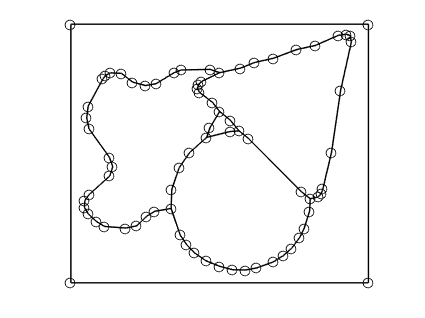

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end

% image to polygon boundary
boundsRaw = im2Bounds( im );
boundsCtrlP = getCtrlPnts( boundsRaw, false, size(im) );

% smooth boundary
lambda = 0.5;   mu = -0.5;  iters = 100;
threshold_num_turning = 0;    threshold_num_vert_Smo = 0;
boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

% simplify polygon boundary
tolerance = 0.3;    threshold_num_vert_Sim = 0;
boundsSimplified = simplifyBounds( boundsSmooth, tolerance, ...
                                        threshold_num_vert_Sim );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

% show all vertices
plotBounds( boundsClear, false, 'ko-' );  

## Coordinates of 4 corners

Before adding points to boundary, we want to know about the x y coordinates of 4 corners in polygonal boundaries .

The image size is

size(im)

ans =     80    92


The height and width of the input image is 80 and 92, respectively. 

So the x y coordinates of 4 corners in polygonal boundaries will be

corners = [0.5, 0.5] + [ 0, 0; 
                         size(im,2), 0; 
                         size(im,2), size(im,1);
                         0, size(im,1) ];
corners

corners =     0.5000    0.5000
   92.5000    0.5000
   92.5000   80.5000
    0.5000   80.5000


The midpoint in the bottom boundary is

xyMidBottom = 0.5*(corners(1,:) + corners(2,:));

We will use these points later.

% upper right corrner
xUpRight = corners(3,1);
yUpRight = corners(3,2);

% upper left corner
xUpLeft = corners(4,1);
yUpLeft = corners(4,2);

## Add midpoint to the bottom edge

We can use function addPnt2Bound to add a point to polygonal boundaries. 

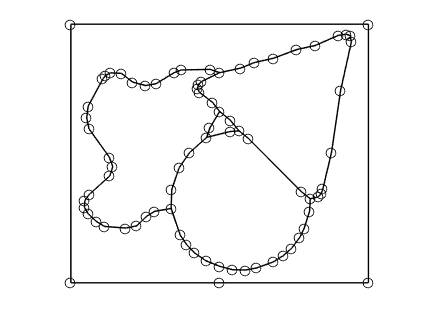

tol_dist = 1e-2;    % distance tolerance
boundsNew = addPnt2Bound( xyMidBottom, boundsClear, tol_dist );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

We saw that the midpoint of the bottom edge is added to the boundary. 

When we generate finite element mesh, the mesh will have this point in the vertices. The midpoint maybe useful when defining boundary condition in some cases. 

## Add a point near the bottom edge

The point to be added does not have to lie exactly on the pristine boundary. The point can have some distance away from the pristine boundary. Check the following example. 

Here we set distance tolerance 'tol_dist' to 8. If the shortest distance between the point and the pristine boundary is less than 'tol_dist', the point will be added to the boundary. Otherwise, the point will not be added.

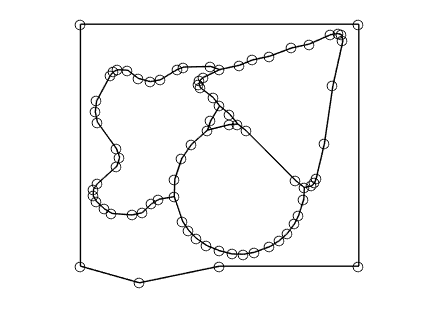

point = [20,-5];
tol_dist = 8;    % distance tolerance
boundsNew = addPnt2Bound( point, boundsNew, tol_dist );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

## Add multiple points to the upper edge

We can add multiple point to the boundary. 

Suppose we want to add 58 points between the upper left corner and the upper right corner. Let's define these points.

numPnt = 58;
x = linspace( xUpLeft, xUpRight, numPnt+2 )';
y = linspace( yUpLeft, yUpRight, numPnt+2 )';
points = [x,y];

Add these points to the boundary. 

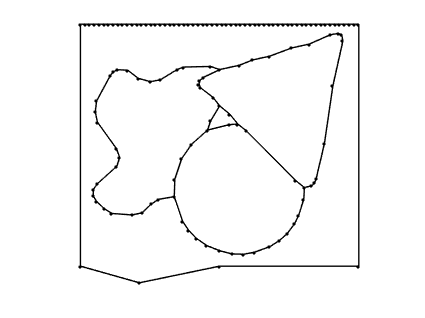

tol_dist = 1e-2;    % distance tolerance
boundsNew = addPnt2Bound( points, boundsNew, tol_dist );

% show all vertices
plotBounds( boundsNew, false, 'k.-' );  

## Generate mesh

We use function poly2mesh to generate mesh.

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsNew );

hmax = 500; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                156                208
         10                170                428
         13                173                468


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                234                208
         10                234                208
         20                240               1431
         30                243               1478
         30                243               1478


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

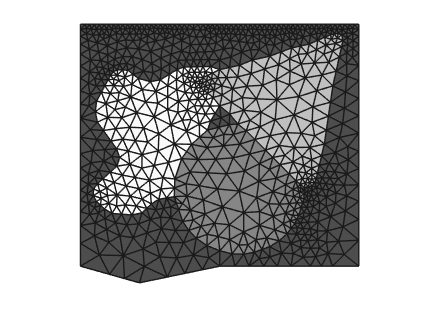

plotMeshes(vert,tria,tnum);

Awesome! We saw that the mesh near the upper boundary is denser due to the inserted nodes.

## Add points to a specific polyline

We can use function addPnt2Bound to add points to a specific polyline.

Suppose we are interested in polygon - boundsClear{1}{2}. Let's plot it.

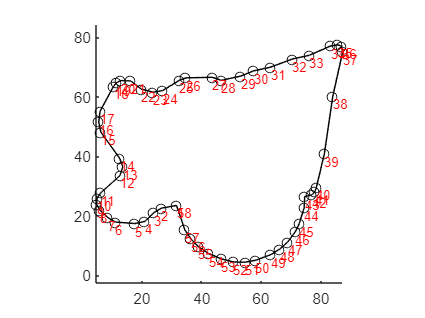

poly = boundsClear{1}{2};

figure; hold on; axis equal
plot( poly(:,1), poly(:,2), 'ko-' );

% add numbering
for i = 1: length(poly)
    text( poly(i,1), poly(i,2), num2str(i), ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'top', ...
        'FontSize', 8, 'Color', 'red');
end
hold off

Suppose we are interested in the polyline between vertex 37 and vertex 40. Let's extract it. 

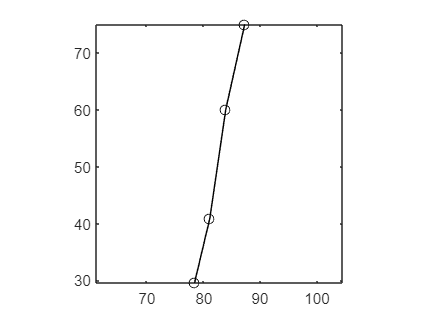

polyline = poly(37:40,:);
plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

Then, we can add more vertices to the interested polyline by repeatedly inserting midpoints to edges. We do this by function insertMidPnt.

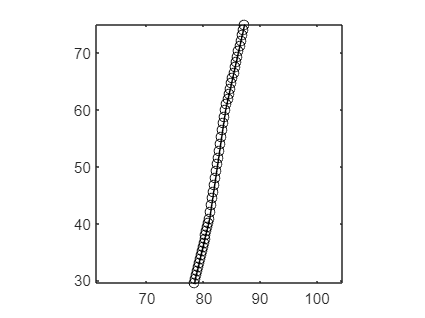

polyline = insertMidPnt( polyline );
polyline = insertMidPnt( polyline );
polyline = insertMidPnt( polyline );
polyline = insertMidPnt( polyline );
plot( polyline(:,1), polyline(:,2), 'ko-' ); axis equal

Add the polyline to the bounday.

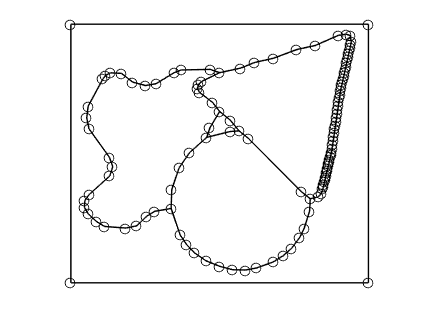

tol_dist = 1e-2;    % distance tolerance
boundsNew = addPnt2Bound( polyline, boundsClear, tol_dist );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

We saw the added nodes.

## Generate mesh

We use function poly2mesh to generate mesh. 

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsNew );

hmax = 500; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
[ vert,tria,tnum,vert2,tria2 ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                148                238
         10                166                456
         16                167                588


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                232                238
         11                233                238
         20                238               1801
         23                238               1817


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                538               1793
     

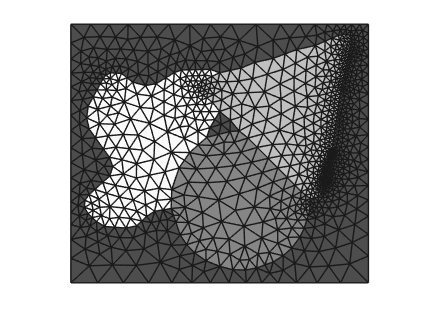

plotMeshes(vert,tria,tnum);

Awesome! We saw that the mesh near the polyline is denser due to the inserted nodes.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo